clear
close
clc

runs=10

load('Datos\sonar.mat')
addpath Funciones\

distanciasMatlab=["euclidean"; "squaredeuclidean"; "seuclidean"; "cityblock"; "minkowski"; "chebychev"; "cosine"; "correlation"; "spearman"];

` 1 = Metal`

`-1 = Roca`

## Clasificador por Distancias "EuclideaClasificacion"

[https://www.youtube.com/watch?v=bmswrj74ePs](https://www.youtube.com/watch?v=bmswrj74ePs)

## PARTE 1

[https://www.youtube.com/watch?v=HhiDgrhJa2s](https://www.youtube.com/watch?v=HhiDgrhJa2s)

% [MatrizConfusion,randomMetal,randomRoca] = parte1funcion(sonarMetal,sonarRoca,"euclidean",67,22,22,59,19,19);


## `PARTE 2`

numeroDistancias=9 %tamaño de vector de distancias
numeroPatronesM=111 %numero de patrones que hay para la clase 1
numeroPatronesR=97 %numero de patrones que hay para la clase 2


Entradas

    database c1 sonarMetal

    database c2 sonarRoca

    iterador de distancia

    numerodeTraining para Metal            ->111*0,6     ->67

    numerode Validation para Metal         ->111*0,2    ->22

    numerodeTest para Metal                    ->111*0,2     ->22

    numerodeTraining para Roca                ->97*0,6    ->59

    numerode Validation para Roca            ->97*0,2    ->19

    numerodeTest para Roca                    ->97*0,2    ->19

                                        Mt=67 %
                                        Mv=22 %
                                        Mte=22 %
                                        Rt=59 %
                                        Rv=19 % 
                                        Rte=19 %

Salidas

    MatrizConfusion

    randomMetal    

    randomRoca 


MatrizConfusion=zeros(numeroDistancias,12);
randomMetal=zeros(numeroDistancias,numeroPatronesM);
randomRoca=zeros(numeroDistancias,numeroPatronesR);

for i=1:numeroDistancias
    iteradorDistancias=distanciasMatlab(i)
    [MatrizConfusion(i,:),randomMetal(i,:),randomRoca(i,:)] = parte1funcion(sonarMetal,sonarRoca,iteradorDistancias,Mt,Mv,Mte,Rt,Rv,Rte);
end; clear i iteradorDistancias

## Parte 3

[ExactitudPrecisionTodasDistancias(:,1),ExactitudPrecisionTodasDistancias(:,4)] = funcionPaso2(MatrizConfusion(:,1:4))
[ExactitudPrecisionTodasDistancias(:,2),ExactitudPrecisionTodasDistancias(:,5)] = funcionPaso2(MatrizConfusion(:,5:8))
[ExactitudPrecisionTodasDistancias(:,3),ExactitudPrecisionTodasDistancias(:,6)] = funcionPaso2(MatrizConfusion(:,9:12))

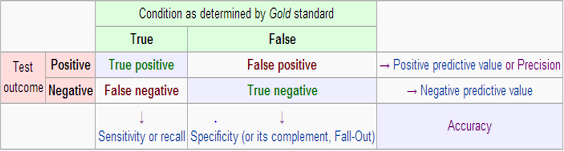

    

  

## PARA LAS MEJORES DISTANCIAS

MejoresDistanciasMatlab=["euclidean"; "cityblock"; "cosine"; "correlation"; "spearman"];

MejorDistancia=MejoresDistanciasMatlab(1)
[EuclideanMatrizConfusion,EuclideanrandomMetal,EuclideanrandomRoca,MediaEuclidean,StdEuclidean] = mejorDistancia(runs,MejorDistancia,numeroPatronesM,numeroPatronesR,sonarMetal,sonarRoca,Mt,Mv,Mte,Rt,Rv,Rte)

MejorDistancia=MejoresDistanciasMatlab(2)
[cityblockMatrizConfusion,cityblockrandomMetal,cityblockrandomRoca,Mediacityblock,Stdcityblock] = mejorDistancia(runs,MejorDistancia,numeroPatronesM,numeroPatronesR,sonarMetal,sonarRoca,Mt,Mv,Mte,Rt,Rv,Rte)

MejorDistancia=MejoresDistanciasMatlab(3)
[cosineMatrizConfusion,cosinerandomMetal,cosinerandomRoca,Mediacosine,Stdcosine] = mejorDistancia(runs,MejorDistancia,numeroPatronesM,numeroPatronesR,sonarMetal,sonarRoca,Mt,Mv,Mte,Rt,Rv,Rte)

MejorDistancia=MejoresDistanciasMatlab(4)
[correlationMatrizConfusion,correlationrandomMetal,correlationrandomRoca,Mediacorrelation,Stdcorrelation] = mejorDistancia(runs,MejorDistancia,numeroPatronesM,numeroPatronesR,sonarMetal,sonarRoca,Mt,Mv,Mte,Rt,Rv,Rte)

MejorDistancia=MejoresDistanciasMatlab(5)
[spearmanMatrizConfusion,spearmanrandomMetal,spearmanrandomRoca,Mediaspearman,Stdspearman] = mejorDistancia(runs,MejorDistancia,numeroPatronesM,numeroPatronesR,sonarMetal,sonarRoca,Mt,Mv,Mte,Rt,Rv,Rte)


medias=[MediaEuclidean; Mediacityblock; Mediacosine; Mediacorrelation; Mediaspearman]
desviacionesEstandar=[StdEuclidean; Stdcityblock; Stdcosine; Stdcorrelation; Stdspearman]

rmpath Funciones\